# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Wpływ danych na dokładność rozwiązania - błędy zaokrągleń

Oprócz złożoności i problemów z rozwiązywaniem dużych układów równań istotnym problemem jest dokładność uzyskanego wyniku. Wpływ na nią mają przede wszystkim:

- Dane wejściowe w postaci macierzy ***A*** i wektora ***b***

- Zastosowana metoda rozwiązania

Pierwszy z wyżej wymienionych punktów często może być daleko bardziej znaczy niż drugi. Poniższy skrypt rozwiązuje dwa układy równań generowane według pewnego wzorca. Jeden z tych wzorców jest korzystny, a drugi niekorzystny - różnią się współczynnikiem uwarunkowania, o którym powiemy sobie dalej. Zwróć uwagę jak błąd (tym razem wyrażony w % żeby bardziej przemawiał do wyobraźni) zmienia się wraz ze wzrostem rozmiaru układu równań.

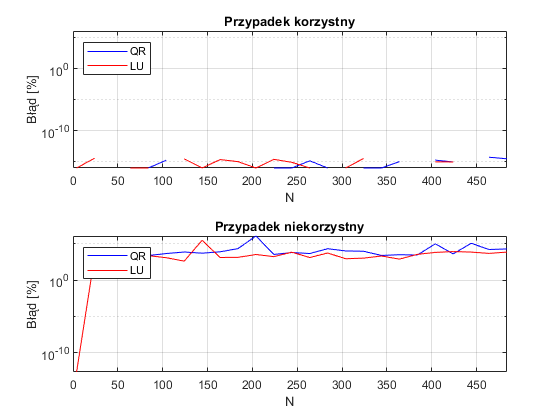

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jamik ma być
% zwiększana ilość równań zaczynając od 4

Nmax=500;
step=20;

bladQR_1=[];bladLU_1=[];bladQR_2=[];bladLU_2=[];
N=[];maxNumCompThreads(1);

%Generujemy losowy układ równań o rozwiązaniu będącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
A1=magic(i)+10*eye(i);        % pierwsza maceirz - korzystna
A2=hilb(i);                   % druga macierz - niekorzystna

%Generowanie wektora b dla rozwiązania będącego wektorem samych jedynek
b1=sum(A1,2);
b2=sum(A2,2);

%Rozwiazanie pierwszego układu równań
[timeAll, timeSimple, error]=solveUsingQRFactorization(A1,b1);
bladQR_1=[bladQR_1 error];N=[N i];warning('off');
[timeAll, timeSimple, error]=solveUsingLUFactorization(A1,b1);
bladLU_1=[bladLU_1 error];

%Rozwiązanie drugiego układu równań
[timeAll, timeSimple, error]=solveUsingQRFactorization(A2,b2);
bladQR_2=[bladQR_2 error];
[timeAll, timeSimple, error]=solveUsingLUFactorization(A2,b2);
bladLU_2=[bladLU_2 error];

%Rysowanie - skala logarytmiczna
figure(1)
tiledlayout(2,1)
nexttile
semilogy(N,bladQR_1*100+1e-16,'b',N,bladLU_1*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest');axis([0 max(N) 0 (100*max([bladQR_1 bladQR_2 bladLU_1 bladLU_2])+1e-16) ]); title("Przypadek korzystny");
nexttile
semilogy(N,bladQR_2*100+1e-16,'b',N,bladLU_2*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest');axis([0 max(N) 0 (100*max([bladQR_1 bladQR_2 bladLU_1 bladLU_2])+1e-16) ]);
title("Przypadek niekorzystny");

waitbar(i / Nmax);
end

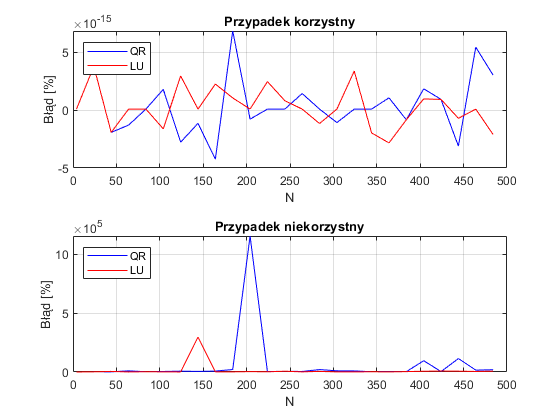

fprintf("Ten sam wykres ale w skali liniowej - zwróć uwagę na rząd wielkości!")
%Rysowanie - skala liniowa
figure(2)
tiledlayout(2,1)
nexttile
plot(N,bladQR_1*100+1e-16,'b',N,bladLU_1*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest'); title("Przypadek korzystny");
nexttile
plot(N,bladQR_2*100+1e-16,'b',N,bladLU_2*100+1e-16,'r');xlabel("N");ylabel("Błąd [%]");grid on; 
legend("QR", "LU",'Location','northwest');
title("Przypadek niekorzystny");


close(h);warning('on');

 

## Wykorzystywane funkcje

function [timeAll, timeSimple, error]=solveUsingQRFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład QR
[Q,R]=qr(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą QR w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
y=Q'*b; 
x=R\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakładając, że rozwiązaniem jest wektor jedynek  
error=(norm(x - ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end

function [timeAll, timeSimple, error]=solveUsingLUFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład LU
%[L,U,P]=lu(A);
[L,U]=lu(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą LU w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
x = U\(L\b);
% Rozpisane na dwie linijki byłoby y = L\(P*b); x = U\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakłądając, ze rozwiazaniem jest wektor jedynek
error=(norm(x - ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end
